HarfRateIdealdelta = calcIdealdelta(HarfRateMatrix)

%  ans = calcIntegralSameRate(FTRateMatrix,plotFTRate,FTtheorval,plotFTIdealRate)
%  plotRgraf(ans)
T = calcIntegral(plotDataTable,theoreticalvalue,plotIdealTable)

T = フィールドをもつ 1×7 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


buff = T(6)

buff = フィールドをもつ struct :
                name: 'Lin103'
       integralvalue: 0.4340
    theoreticalvalue: 0.4550
       idealcalvalue: 0.4454
      inte_theoratio: 0.9538
     inte_idealratio: 0.9742


T(6) = T(3)

T = フィールドをもつ 1×7 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


buff2 = T(5)

buff2 = フィールドをもつ struct :
                name: 'Lin95'
       integralvalue: 0.3255
    theoreticalvalue: 0.3457
       idealcalvalue: 0.3333
      inte_theoratio: 0.9417
     inte_idealratio: 0.9766


T(5) = buff

T = フィールドをもつ 1×7 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T(3) = T(2)

T = フィールドをもつ 1×7 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T(2) = T(1)

T = フィールドをもつ 1×7 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T(1) = T(4)

T = フィールドをもつ 1×7 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T(4) = buff2

T = フィールドをもつ 1×7 の struct 配列:
    name
    integralvalue
    theoreticalvalue
    idealcalvalue
    inte_theoratio
    inte_idealratio


T = struct2table(T)

T = 7×6 table
        name        integralvalue    theoreticalvalue    idealcalvalue    inte_theoratio    inte_idealratio
    ____________    _____________    ________________    _____________    ______________    _______________

    'Linear63'         0.35237             0.375            0.35713          0.93966            0.98667    
    'Haming74'         0.31785           0.33673            0.32142          0.94393            0.98889    
    'ExHaming84'       0.35833             0.375             0.3611          0.95553            0.99231    
    'Lin95'            0.32552           0.34567            0.33333          0.94172            0.97659    
    'Lin103'           0.43396             0.455            0.44545          0.95375            0.97421    
    'Haming1511'       0.22253            0.2311            0.22499          0.96294            0.98908    
    'Lin2016'          0.17395              0.18            0.17618          0.96637            0.98731    


hold on
 xlabel('n','FontSize',20);
 B = [1 2 3 4 5 6 7]'

B =      1
     2
     3
     4
     5
     6
     7


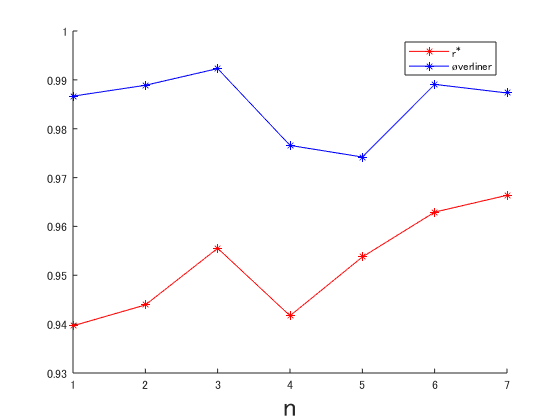

 %x軸にセルの１列目を、それ以外をy軸にそれぞれ使用してグラフを作成
    plot(T{:,5},'r*-');
    plot(T{:,6},'b*-');
    legend('r^*','\overline{r}');

 hold off

strage = struct('avrdelta',[],'mindelta',[],'minmatrix',[]);

strage = randammatrix(12,6)